# Support vector classifiers

We will study the behavior of the support vector classifier for binary classification. The support vector classifier finds and uses a linear discriminant to separate two classes. This classifier is the precursor to the support vector machine (SVM) which uses kernel functions and thus can use a nonlinear discriminant in general.

### Training the classifier with `fitcsvm`

Generate two-dimensional test data for two classes. The data in the first class comes from a normal distribution centered at (-1.8, -1.8) and the data in the second class comes from a normal distribution centered at (1.8, 1.8). Use the slider to set the random number seed if you wish.

rng(78);       % random number seed
n = 20; % number of data points in each of two classes
x = [randn(n,2)+1.8; randn(n,2)-1.8]; % data points
y = [ones(n,1); -ones(n,1)];          % class labels

Train the support vector classifier with the above data. An input to the training method is an inverse regularization parameter $C$ sometimes called the box constraint parameter. The output of the training is a set of dual weights $0 \le a_i \le C$, one weight for each point. For the problem as we have set it up, MATLAB will use Sequential Minimal Optimization (SMO) to find the $\alpha_i$.

C = 63; % inverse regularization parameter
model = fitcsvm(x, y, "BoxConstraint", C);

The trained output `model` is an instance of a class that contains several properties, and you can see some of these properties here.

model

model =   ClassificationSVM
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [-1 1]
           ScoreTransform: 'none'
          NumObservations: 40
                    Alpha: [3×1 double]
                     Bias: 0.8276
         KernelParameters: [1×1 struct]
           BoxConstraints: [40×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [40×1 logical]
                   Solver: 'SMO'

  Properties, Methods


Most of the dual weights $\alpha_i$ obtained by the optimization will be zero; the data points corresponding to nonzero $\alpha_i$ are called support vectors. The nonzero $\alpha_i$ are stored in the vector `Alpha`. The logical vector `IsSupportVector` contains entries that indicate whether each point is a support vector. Thus, if you wanted to construct the complete vector of dual weights, you could write:

alpha = zeros(2*n,1);
alpha(model.IsSupportVector) = model.Alpha;

The primal weights can be obtained from the dual weights $\alpha_i$, and they are also stored in `model`. Let $w$ denote the vector of primal weights, and $w_0$ denote the bias weight.

w  = model.Beta

w =     1.2352
    0.9734


w0 = model.Bias

w0 = 0.8276

This lets us write the discriminant function in the primal variables, $f(x) = w_0 + w^T x$.

### Discriminant function and `predict` function

The discriminant function for the support vector classifier is simply the *normalized* signed distance of a point $x$ to the discriminant. A point on a margin boundary has a normalized distance of 1. Assuming your class labels are +1 and -1, the discriminant function in terms of the $\alpha_i$ is


$$w_0 + \sum_i \alpha_i \, y_i \, x_i^T \, x$$


Positive values of the discriminant function predict one class and negative values predict the other class. Above, the bias value $w_0$ can be computed from the $\alpha_i$ in a variety of ways; to make sure you have a $w_0$ that was computed in a stable manner, you can retrieve it from `model` (which we have already done above).

In the above expression for the discriminant, you can see that points that are not support vectors are not needed. Thus you can implement a discriminant function very efficiently to make predictions for new data. Here, we make use of the fact that `model.SupportVectors` is a matrix whose rows are the support vectors.

discr_fun = @(x) w0 + model.Alpha'* ...
    ((model.SupportVectorLabels).*(model.SupportVectors*(x')));

Let's use this function to calculate the value of the discriminant function for two points, and thus classify these two points.

point1 = [ 0.5,  0.5];
discr_fun(point1)

ans = 1.9319

point2 = [-0.5, -0.5];
discr_fun(point2)

ans = -0.2767

Of course, you can also use the `predict` function provided by MATLAB, which outputs a predicted label and a SVM classification score. The classification score is the signed distance to the discriminant for each class.

[label, score] = predict(model, point1)

label = 1

score =    -1.9319    1.9319


[label, score] = predict(model, point2)

label = -1

score =     0.2767   -0.2767


The results of using your own discriminant function and that of `predict` are consistent.

### Visualizing the discriminant

For this two-dimensional problem, we can easily visualize the linear discriminant. For this, we'll use the linear discriminant in the primal variables, $w_0 + w^T x$, where $w$ is computed from $w = \sum_i \alpha_i \, y_i \, x_i$. We should see that this $w$ agrees with the value of `model.Beta` above.

w = model.SupportVectors' * (model.Alpha .* model.SupportVectorLabels)

w =     1.2352
    0.9734


Now we plot the discriminant and the margin boundaries, along with the training data. The support vectors are outlined with square boxes.

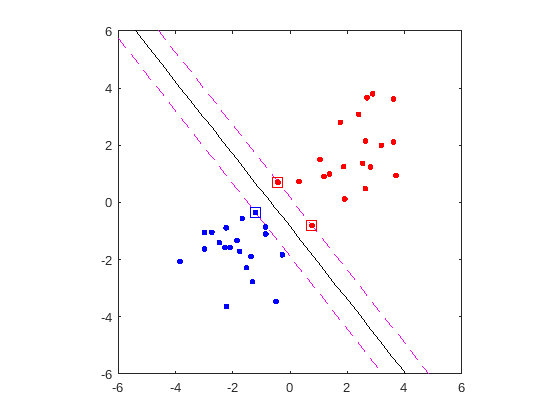

clf
fplot(@(x) -w0/w(2) -w(1)/w(2)*x, [-6 6], 'k-')
hold on
fplot(@(x) -w0/w(2) -w(1)/w(2)*x -1/w(2), [-6 6], 'm--') % margin boundary
fplot(@(x) -w0/w(2) -w(1)/w(2)*x +1/w(2), [-6 6], 'm--') % margin boundary
gscatter(x(:,1), x(:,2), y, 'br', '.', 10, 'off')        % scatter plot by group
gscatter(model.SupportVectors(:,1), model.SupportVectors(:,2), ...
    model.SupportVectorLabels, 'br', 's', 10, 'off')
axis equal
ylim([-6 6])

We also plot the margins with dotted lines. To formula for this line is the same as the formula for the discriminant, except that the intercept should be increased or decreased by `1/w(2)`. Explain why!

From the figure, it appears that there are three points equidistant from the discriminant. These are the three support vectors in this case. We can check that the second support vector has a distance of 1 (or close to it) from the discriminant.

sv=model.SupportVectors;
discr_fun(sv(2,:))

ans = 0.9998

### Taking it further

- Experiment with the inverse regularization parameter and explain what you see. Are there cases where the data are on the "wrong" side of the margin?

- If there are two data points, explain geometrically whether the discriminant is uniquely determined.

- Explain the formula used above for plotting the two margins.